%' BCH comparision
clc;
clf;
clear;

disp("K = 5")

K = 5


M = 4;
n = 2^M-1;   % Codeword length
k = 5;       % Message length
nwords = 1000; % Number of words to encode

msgTx = gf(randi([0 1],nwords,k));
t = bchnumerr(n,k)

t = 3


enc = bchenc(msgTx,n,k);
z = enc.x;
z = double(z);
y =1-2.*z;

SNR_arr = [0:2:10]; 

error_arr = zeros(1,length(SNR_arr));
for a = 1:length(SNR_arr)
    
    % awqn noise
    r = myAWGN(y,SNR_arr(a),size(y,1),size(y,2));
    c_cap =  zeros(size(r,1),size(r,2));
    % decoding-hard
    for i=1:size(y,1)
        for j=1:size(y,2)
            if r(i,j) >=0
                c_cap(i,j) = 0;
            else
                 c_cap(i,j) = 1;
            end
            
        end
    end
    c_cap= uint32(c_cap);
    m = enc.m;
    prim_poly=enc.prim_poly;
    q = gf(c_cap,m,prim_poly); 
    msgRx = bchdec(q,n,k);
 
    out = msgRx.x;
    out = double(out);
    in = msgTx.x;
    in = double(in);
    error = sum(sum(abs(in-out)))/(size(in,1)*size(in,2));
    error_arr(a) = error;
end


semilogy(SNR_arr,error_arr)
xlabel("SNR/bit (dB)")
ylabel("BER")
title("BCH Code")
grid on;

clear;
hold on
disp("K = 7")

K = 7


M = 4;
n = 2^M-1;
k = 7;       % Message length
nwords = 1000; % Number of words to encode

msgTx = gf(randi([0 1],nwords,k));
t = bchnumerr(n,k)

t = 2


enc = bchenc(msgTx,n,k);
z = enc.x;
z = double(z);
y =1-2.*z;

SNR_arr = [0:2:10]; 

error_arr = zeros(1,length(SNR_arr));
for a = 1:length(SNR_arr)
    
    % awqn noise
    r = myAWGN(y,SNR_arr(a),size(y,1),size(y,2));
    c_cap =  zeros(size(r,1),size(r,2));
    % decoding-hard
    for i=1:size(y,1)
        for j=1:size(y,2)
            if r(i,j) >=0
                c_cap(i,j) = 0;
            else
                 c_cap(i,j) = 1;
            end
            
        end
    end
    c_cap= uint32(c_cap);
    m = enc.m;
    prim_poly=enc.prim_poly;
    q = gf(c_cap,m,prim_poly); 
    msgRx = bchdec(q,n,k);
 
    out = msgRx.x;
    out = double(out);
    in = msgTx.x;
    in = double(in);
    error = sum(sum(abs(in-out)))/(size(in,1)*size(in,2));
    error_arr(a) = error;
end


semilogy(SNR_arr,error_arr)
xlabel("SNR/bit (dB)")
ylabel("BER")
title("BCH Code")
grid on;
%save("BCH_AWGN","error_arr")

clear;
hold on
disp("K = 11")

K = 11


M = 4;
n = 2^M-1;
k = 11;       % Message length
nwords = 1000; % Number of words to encode

msgTx = gf(randi([0 1],nwords,k));
t = bchnumerr(n,k)

t = 1

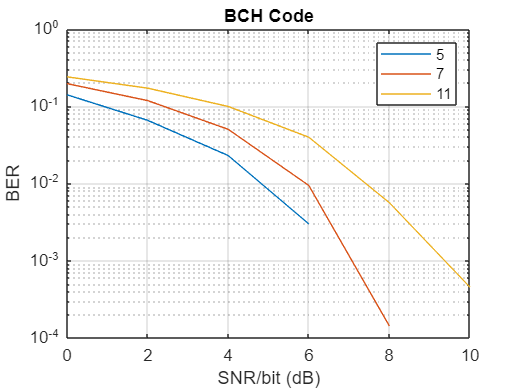


enc = bchenc(msgTx,n,k);
z = enc.x;
z = double(z);
y =1-2.*z;

SNR_arr = [0:2:10]; 

error_arr = zeros(1,length(SNR_arr));
for a = 1:length(SNR_arr)
    
    % awqn noise
    r = myAWGN(y,SNR_arr(a),size(y,1),size(y,2));
    c_cap =  zeros(size(r,1),size(r,2));
    % decoding-hard
    for i=1:size(y,1)
        for j=1:size(y,2)
            if r(i,j) >=0
                c_cap(i,j) = 0;
            else
                 c_cap(i,j) = 1;
            end
            
        end
    end
    c_cap= uint32(c_cap);
    m = enc.m;
    prim_poly=enc.prim_poly;
    q = gf(c_cap,m,prim_poly); 
    msgRx = bchdec(q,n,k);
 
    out = msgRx.x;
    out = double(out);
    in = msgTx.x;
    in = double(in);
    error = sum(sum(abs(in-out)))/(size(in,1)*size(in,2));
    error_arr(a) = error;
end


semilogy(SNR_arr,error_arr)
xlabel("SNR/bit (dB)")
ylabel("BER")
title("BCH Code")
grid on;
legend("5","7","11")

function [r] = myAWGN(y,SNR,n,m)
No = 1/(10^(SNR/10));
    No_2 = No/2*3;
    noise = sqrt(No_2)*randn(n,m);
    r = y + noise;
end